# 深度网络设计器快速入门

路径：

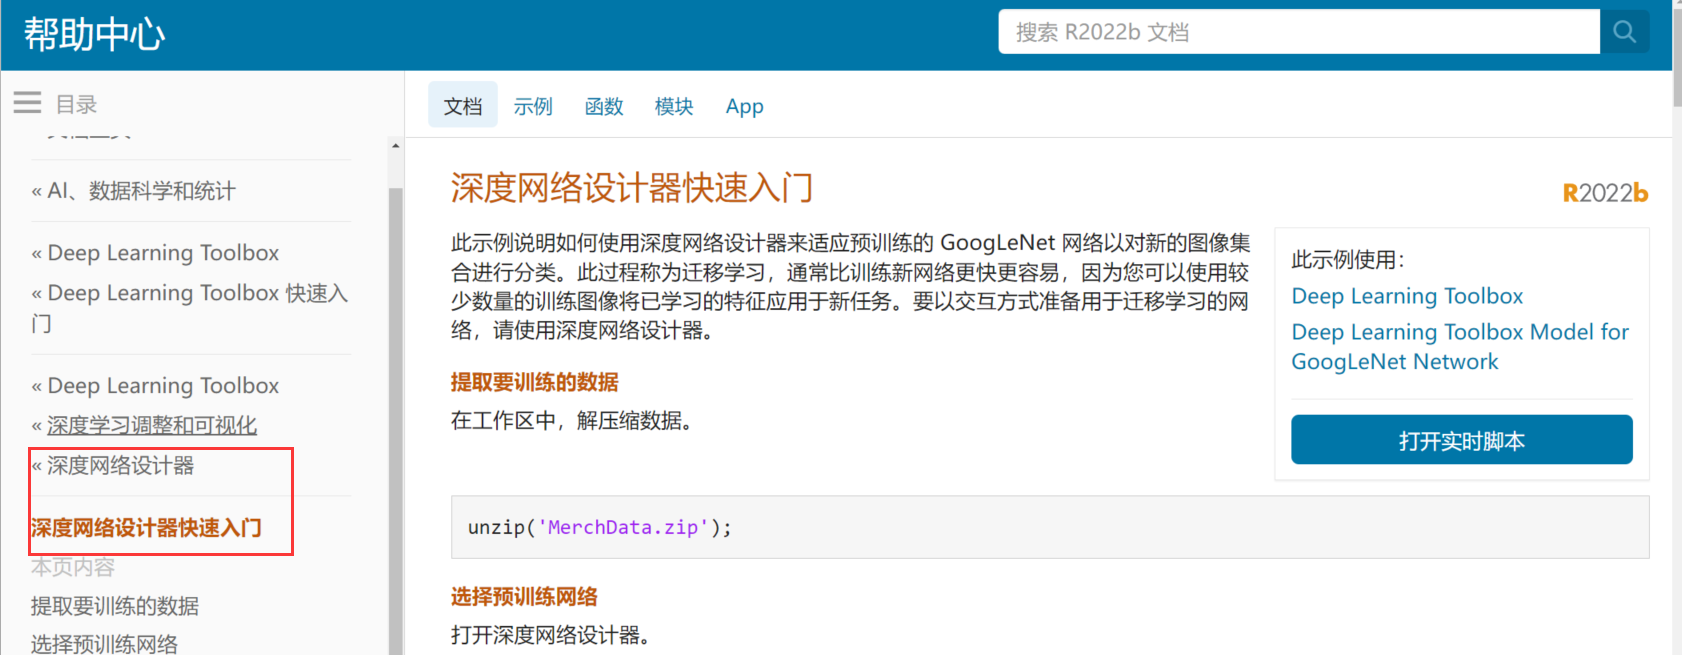

% unzip("MerchData.zip");

% 在命令行执行以下命令：
% deepNetworkDesigner  % 打开深度网络编辑器

根据教程：

- 导入数据；

- 编辑网络；

- 设置训练参数；

- 训练网络；

- 导出网络到工作区。

 导出的结果如下图所示。

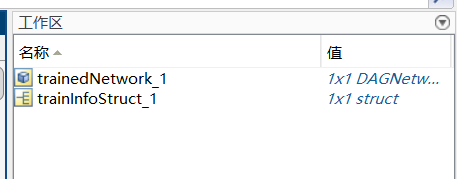

% 存储网络到文件
% save("GoogleNet_image_classify.mat",'trainedNetwork_1');
% save('GoogleNet_traininfoStruct.mat','trainInfoStruct_1');

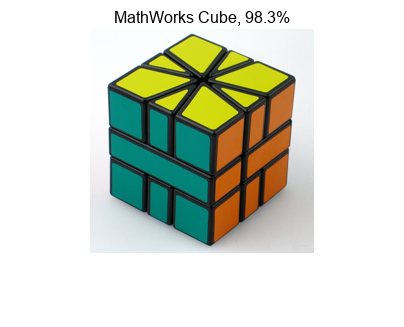

% 使用网络识别图片
load("GoogleNet_image_classify.mat")
% I = imread("MerchDataTest.jpg");
while true
    imgfile = uigetfile("MultiSelect","off", "*.jpg");
    if imgfile ==0
        break
    end
    I = imread(imgfile);
    I = imresize(I, [224 224]);
    
    [YPred, probs] = classify(trainedNetwork_1, I);
    imshow(I);
    label = YPred;
    title(string(label) + ", " + num2str(100*max(probs), 3) + "%");
end

# 总结

人生苦短~拧螺丝还得有趁手的工具。Matlab，是你吗？ 

在官方的这个例子，其实可以快速开发很多应用的。比如人脸识别，物体识别。

例如超市现在的智能电子秤，拍照识别果蔬，减去了人工选择品类的过程。具体思路就是准备自己的训练数据和标签。从MerchData的结构来看，子文件夹的文件名称就是分类标签（一个五个分类），子文件夹里的图片就是训练图片。